# Cleaning Flight Data

## Dataset

The dataset contains approximately 4600 different flights of aircraft number 660. Each flight has measurements from 2 different sensors, one with a frequency of 1 Hz and the other with a frequency of 4 Hz. *(For the purposes of the example, the data has been modified and we will use only a smaller subset - *[*Flight Data from Dashlink*](https://c3.ndc.nasa.gov/dashlink/projects/85/)*)*

### 1 Hz

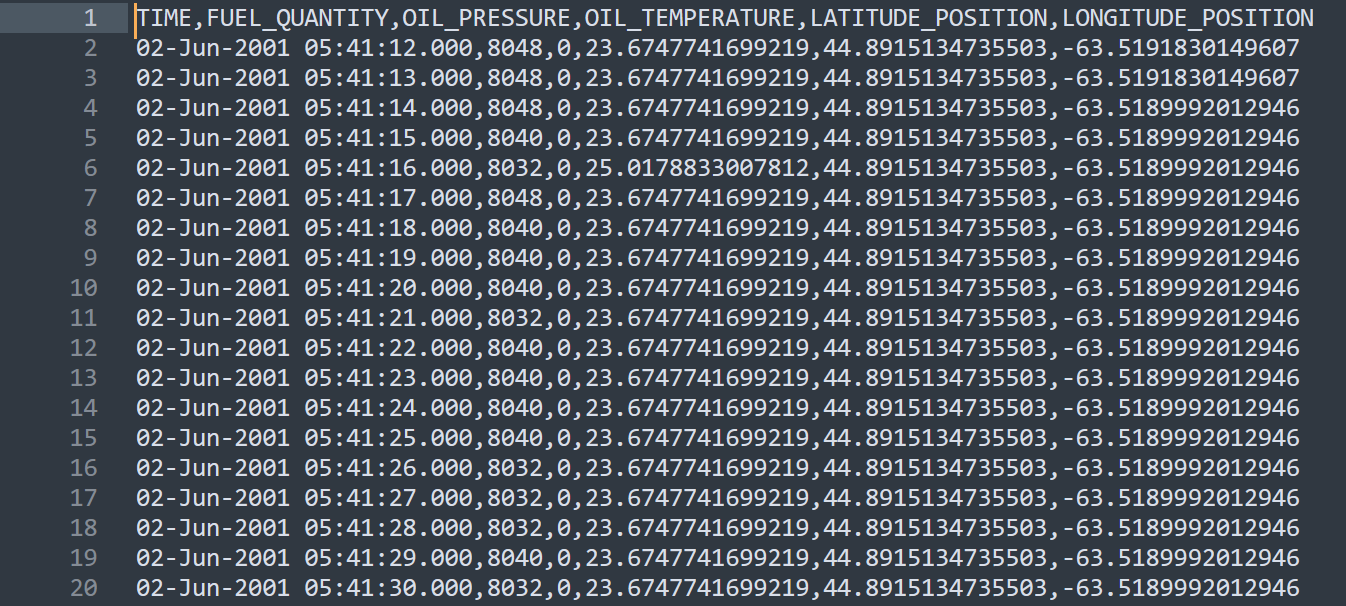

### 4 Hz

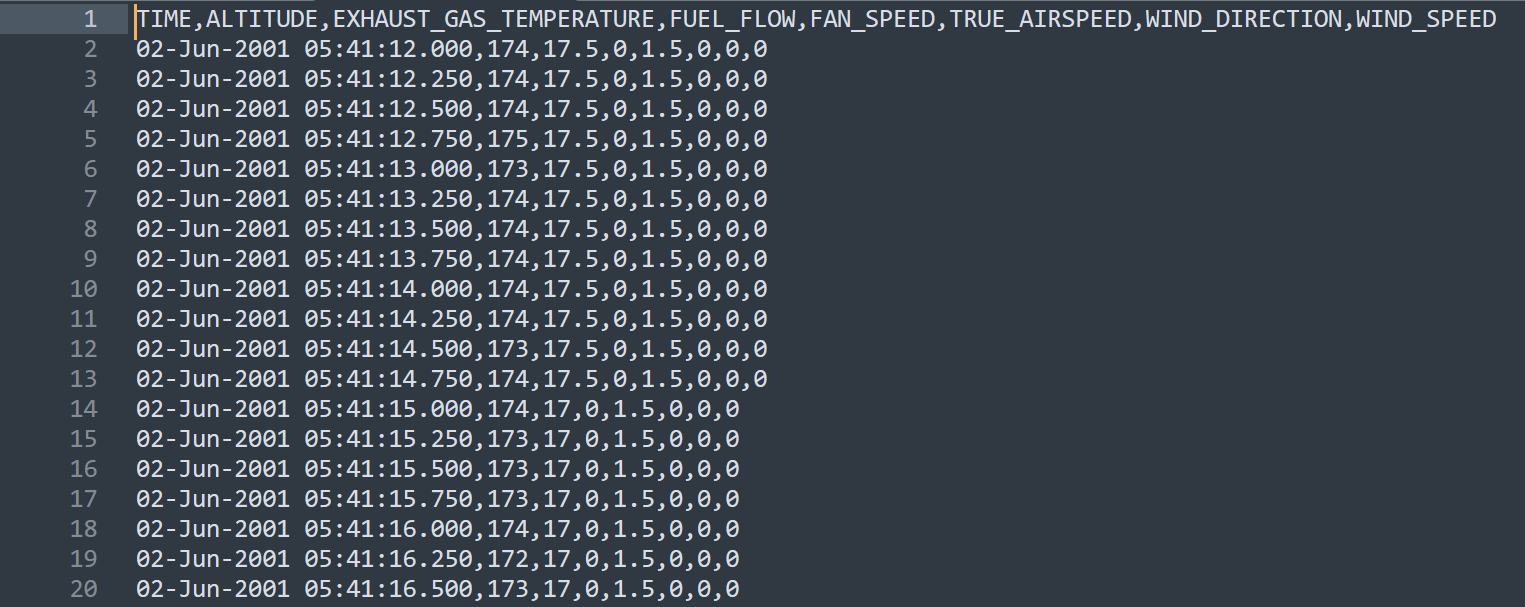

# 1. Import data

Multiple approaches can be used to import data drom a file. You can use Import Data button on the HOME tab. Application allows you to select range, variable rows, output type and create rules for unimportable cells.

Second option can be Live Editor Task - Import Data

- Select Live Editor Tab - Go to Task - Select Import Data

- Select File to import - flightData1HZ.csv

- Rename output variable to -  t1HZ

- Specify type as Timetable

- Look at code 

# 2. Visualise flight route

Lets visualize plane position.

- Select Live Editor Tab - Go to Task - Select Create Plot

- Filter by Category - Geographics Plots

- Select plot type - geoplot

- Select data columns - LatitudePosition, LongitudePosition  

- Convert Task to Code - top right coner - 3 dots - Convert To Code

Plot have serveral parameters to apply for example Line Color and Line Width

% geoplot(t1HZ.LatitudePosition,t1HZ.LongitudePosition,'Color','b','LineWidth',2);

Visualization of geographical plots can be changed as well. Remove % from next command.

% geobasemap colorterrain

# 3. Data processing

Raw data often contains missing data or outliers. Table data can be preprocess via Data Clear APP.

## [Data Cleaner app](https://www.mathworks.com/help/matlab/ref/datacleaner-app.html) (R2022a)

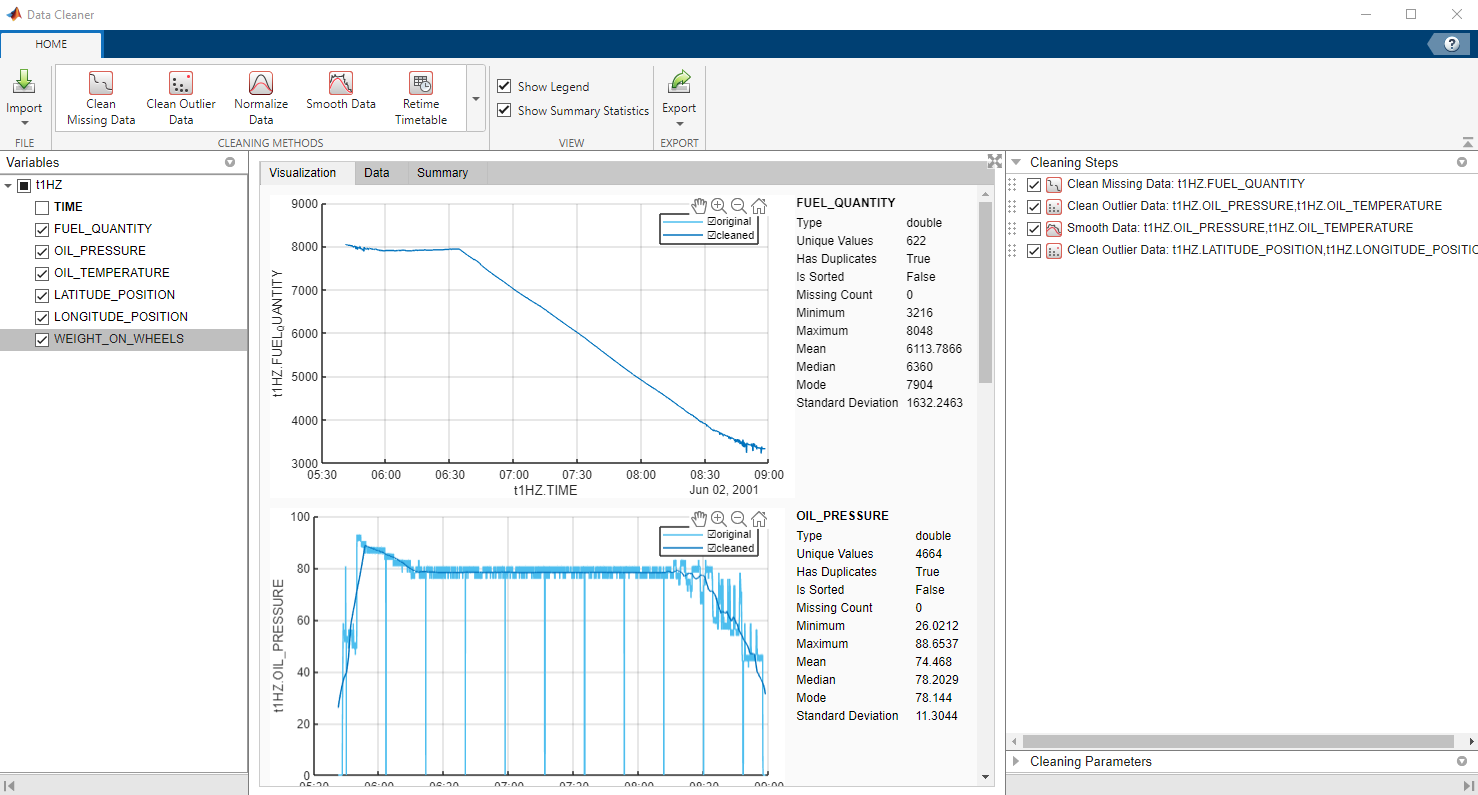

- Select HOME Tab - Clean Data

- Select Import - Import from workspace - t1HZ

- Select Plot Tab and Select all columns with eye icon

- Explore data statistic

- Select Clean Missing Data Button - Table variable - FuelQuantity, Cleaning method - Fill Missing, Fill Method - Linear interpolation. Explore other options. Accept changes

- Select Clean Outlier Data Button - Table variable - OilPressure and OilTemperature, Cleaning method - Fill Outliers, Fill Method - Linear interpolation, Detection method - Moving Median, Window Length - 8, Units - Seconds. Explore other options. Accept changes

- Select Clean Outlier Data Button - Table variable - LatitudePosition,LongitudePosition - Fill Outliers, Fill Method - Previous Value, Detection method - Mean, Explore other options. Accept changes

- Export - Generate Function - Save as - cleanData

% dataCleaner

We can generate a function from the application that can similarly process any number of files.

t1HZ = clean1HZData(t1HZ)

## Let's verify the aircraft's route using the processed data

Plot aircraft´s route using [geoplot](https://www.mathworks.com/help/matlab/ref/geoplot.html) function. 

- t1HZ.LatitudePosition

- t1HZ.LongitudePosition

- Color - blue

- Line Width - 3

- geobasemap - colorterrain

geoplot(t1HZ.LatitudePosition,t1HZ.LongitudePosition,'Color','b','LineWidth',3)
geobasemap colorterrain

# 4. Reading and processing data from the 4 Hz sensor

Use [readtimetable](https://www.mathworks.com/help/matlab/ref/readtimetable.html) function to read the "flightData4HZ.csv" file into variable named **t4HZ**.

t4HZ = readtimetable("flightData4HZ.csv");
t4HZ = clean4HZData(t4HZ)

# 5. Synchronizing two datasets

Lets combine two sensors together. We need to synchronize table.

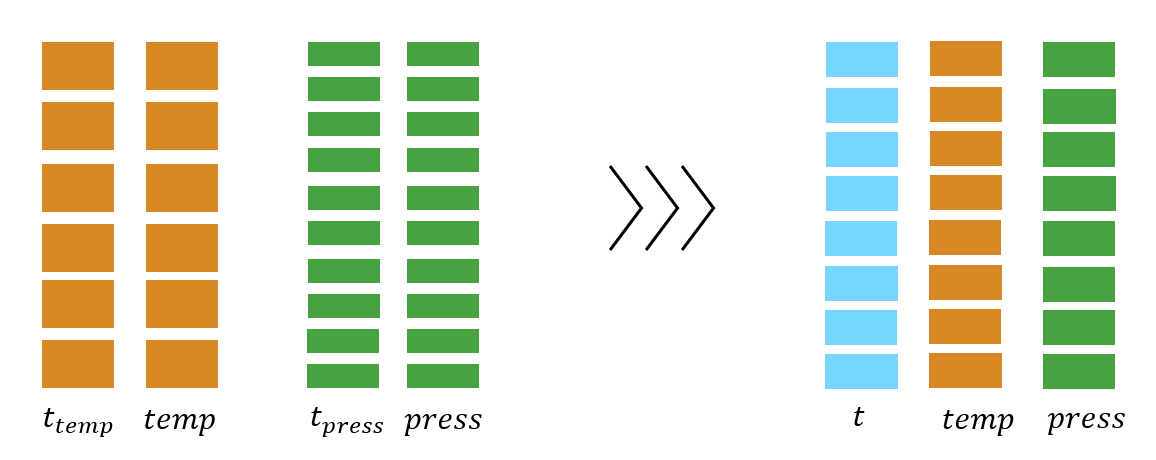

- Select Live Editor Tab - Go to Task - Synchronize tables

- Select input timetables - t1HZ, t4HZ

- Seletion method - Union

- Adjusting Data - General Rule - Linear Interpolation  

# 6. Visualizing timetables using stackedplot

Stackedplot allows you to visualize multiple variables with a common x-axis and compare them synchronously.

- Select Live Editor Tab - Go to Task - Select Create Plot

- Select visualization - stackedplot

- Select data X - t - select  

- Select data X - t - All variables

# 7. Finding data during flight at altitude using ischange

Flight data without climb and descent can be found using the change in altitude. 

% Find change points
changeIndices = ischange(t.Altitude,"variance","MaxNumChanges",2,...
    "SamplePoints",t.Time);

% Display results
clf
plot(t.Time,t.Altitude,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on

% Plot change points
x = repelem(t.Time(changeIndices),3);
y = repmat([ylim(gca) missing]',nnz(changeIndices),1);
plot(x,y,"Color",[51 160 44]/255,"LineWidth",1,"DisplayName","Change points")
title("Number of change points: " + nnz(changeIndices))

hold off
legend
xlabel("Time")
clear x y


Finding the start and end of a flight without climb or descent

% Find the change points
changeIndices = find(changeIndices)
% Find cruise start and end times
cruiseStartTime = t.Time(changeIndices(1))
cruiseEndTime = t.Time(changeIndices(2))

Timetable allows you to select data using [timerange](https://www.mathworks.com/help/releases/R2024b/matlab/ref/timerange.html) function. 

cruiseRange = timerange(cruiseStartTime,cruiseEndTime)

Create new timetable called **tcruise** containing only the cruise data. 

tcruise = t(cruiseRange,:)

Use [stackedplot](https://www.mathworks.com/help/matlab/ref/stackedplot.html) to plot variables in **tcruise**.

stackedplot(tcruise)

# Model True Air Speed

We can model TAS with a regression model trained in the [**Regression Learner app**](https://www.mathworks.com/help/stats/regression-learner-app.html). First we will convert cruise data to table

TAS_table=timetable2table(tcruise);

- Select APPS Tab - search for Regression Learner

- Select New session - From Workspace

- Dataset Variable - TAS_table, Response - True Air Speed, Deselect - Latitude, Longitude from Predictors, Start Session

- Deselect - Use Parallel

- Select - All Quick-To-Train models, Run Train All

- Compare models. You can also explore Feature Selection where you can rank features and other Tabs like Explain 

% regressionLearner